# HW3 Machine Learning - Nika Emami - ne2213

Loading the data, and putting it to test and train sets after shuffling the data:

data = load('dataset.mat');
data.Y(51:100) = -1;
[m,n] = size(data.X);
P = 0.5;
rng(123);
idx = randperm(m);
rd = round(P*m);
x = data.X(idx(1:rd),:) ;
xT = data.X(idx(rd+1:end),:) ;
y = data.Y(idx(1:rd),:) ;
yT = data.Y(idx(rd+1:end),:) ;

Applying svm with linear kernels for different values of c:

num_c = 10;
lin_err = zeros(1,num_c);
for c=1:num_c
    [nsv, alpha, b0] = svc(x,y, 'linear',c);
    yhat = svcoutput(x,y,xT,'linear',alpha,b0,0);
    lin_err(c) = svcerror(x,y,xT,yT,'linear',alpha,b0);
end

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

Plotting the error for the linear kernel:

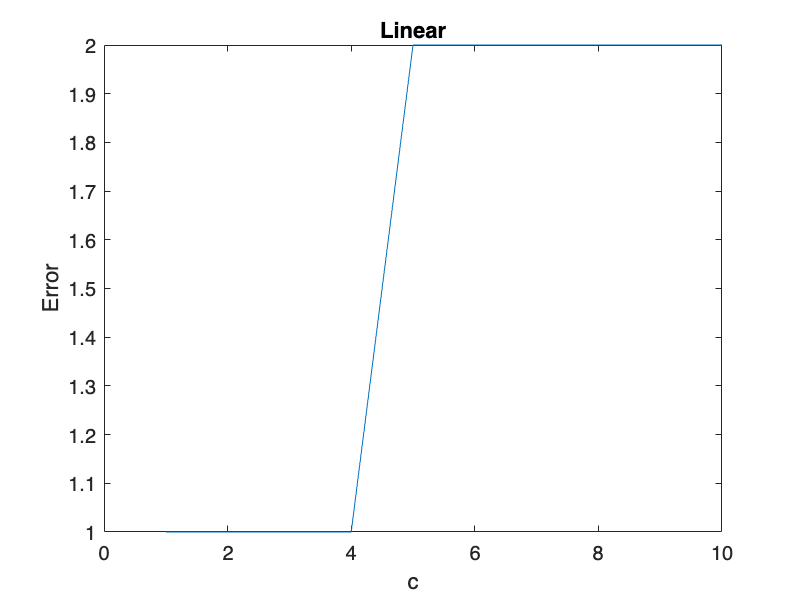

figure
plot( 1:num_c,lin_err);
title('Linear');
xlabel('c');
ylabel('Error');

As it can be seen, by increasing c, the error increases too.

Applying svm with polynomial kernels for different values of c and degrees of the polynomial from 1 to 5:

global p1;
deg_max = 5;
c_list = 1:10;
poly_err = zeros(numel(c_list),deg_max);
for i = 1:numel(c_list)
    for d=1:5
        p1 = d;
        c = c_list(i)
        [nsv,alpha,b0] = svc(x,y,'poly', c);
        poly_err(i, d)= svcerror(x,y,xT,yT,'poly',alpha,b0);
    end
end

c = 1

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 1

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 1

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 1

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 1

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 2

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 2

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 2

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 2

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 2

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 3

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 3

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 3

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 3

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 3

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 4

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 4

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 4

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 4

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 4

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 5

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 5

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 5

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 5

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 5

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 6

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 6

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 6

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 6

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 6

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 7

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 7

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 7

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 7

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 7

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 8

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 8

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 8

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 8

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 8

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 9

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 9

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 9

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 9

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 9

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 10

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 10

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 10

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 10

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

c = 10

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

Plotting the error for the polynomial kernel:

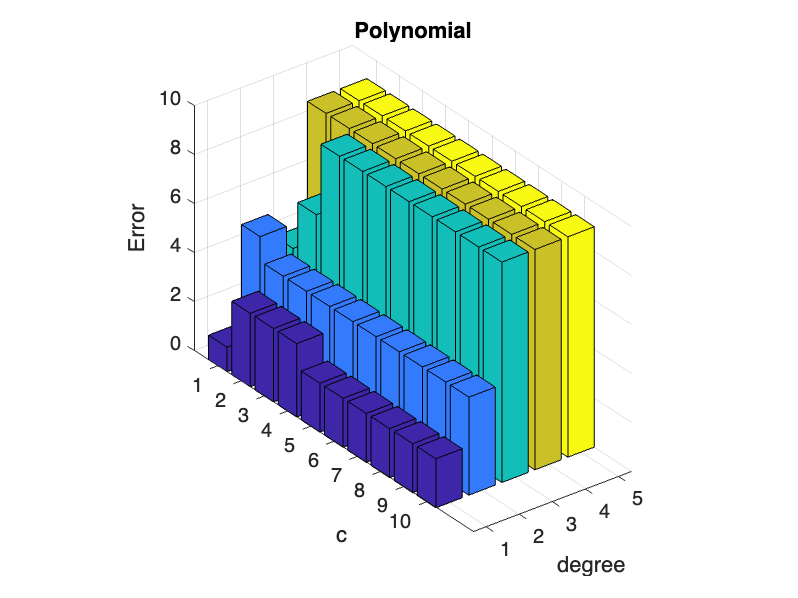

figure
bar3(poly_err)
xlabel ('degree')
ylabel ('c')
zlabel('Error')
title('Polynomial');					

By increasing the polynomial degree, the testing error has increased because the model has overfitted the train data. 

Applying svm with RBF kernels for different values of c and values of sigma (from 0.1 to 1):

sigma = linspace(0.1, 1, 10);
rbf_err = zeros(num_c,numel(sigma));
for c = 1:10
    for i=1:numel(sigma)
        p1 = sigma(i);
        [nsv,alpha,b0]=svc(x,y,'rbf',c);
        rbf_err(c, i)= svcerror(x,y,xT,yT,'rbf',alpha,b0);
    end
end

Support Vector Classification
_____________________________
Constructing ...
Optimising ...
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteri

Plotting the error for the RBF kernel:

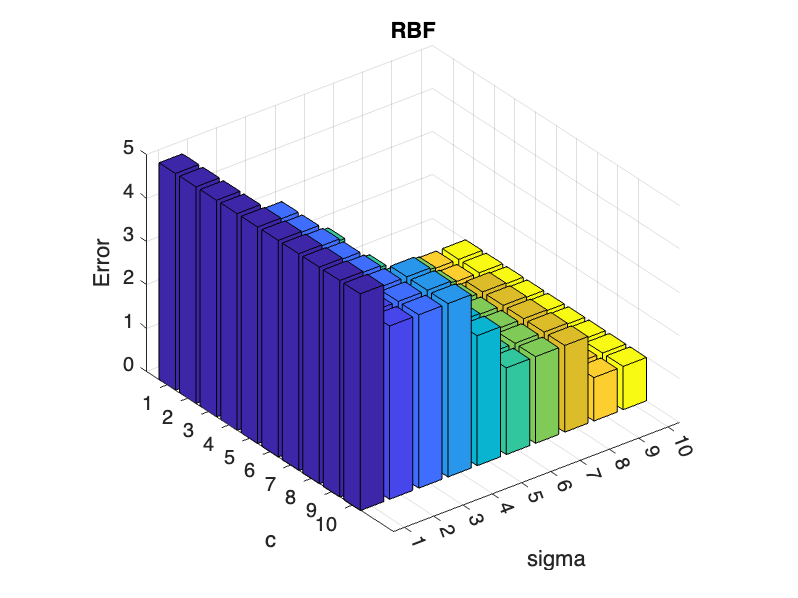

figure
bar3(rbf_err)
xlabel ('sigma')
ylabel ('c')
zlabel('Error')
title('RBF');

As it can be seen, in greater values of sigma, the decision boundary is more flexible, and the test error for bigger sigma is smaller.  